clear 
close all
rng(5)

load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data1.mat')
Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map1.mat")
Data;

RequiredMaps = 100000

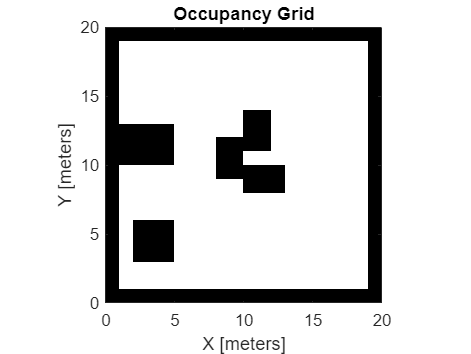

omap;
network = load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\mpnet", "mpnet");
mpnet = network.mpnet;
show(omap)

Map

Map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  

%UAV setup
model = multirotor;
uavPose = [start_y start_x -5 pi/2 0 0]';
uavPose

uavPose =     8.0000
    5.0000
   -5.0000
    1.5708
         0
         0


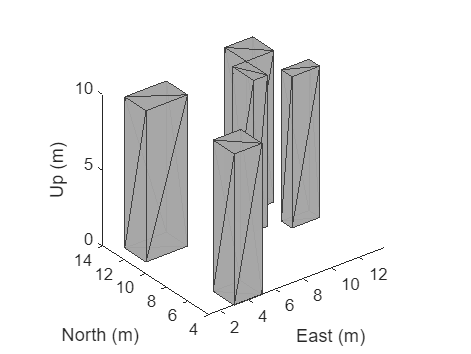

%Scene Setup
scene = uavScenario(UpdateRate=2);
addMesh(scene,"polygon",{[2 11;5 11;5 13;2 13],[0 10]},0.651*ones(1,3))
addMesh(scene,"polygon",{[3 4;5 4;5 6;3 6],[0 10]},0.651*ones(1,3))
addMesh(scene,"polygon",{[9 10;10 10;10 12;9 12],[0 10]},0.651*ones(1,3))
addMesh(scene,"polygon",{[11 9;13 9;13 10;11 10],[0 10]},0.651*ones(1,3))
addMesh(scene,"polygon",{[10 12;12 12;12 14;10 14],[0 10]},0.651*ones(1,3))


show3D(scene);

plat = uavPlatform("UAV",scene, ...
                   ReferenceFrame="NED", ...
                   InitialPosition=uavPose(1:3)', ...
                   InitialOrientation=eul2quat(uavPose(4:6)'));

updateMesh(plat,"quadrotor",{1.5},[0 0 0],eul2tform([0 0 pi]))
lidarmodel = uavLidarPointCloudGenerator(AzimuthResolution=0.3324099, ...
                                         ElevationLimits=[-10 30], ...
                                         AzimuthLimits=[-60 60], ...
                                         ElevationResolution=0.5, ...
                                         MaxRange=10, ...
                                         UpdateRate=2, ...
                                         HasOrganizedOutput=true);

lidar = uavSensor("Lidar",plat,lidarmodel, ...
                  MountingLocation=[0 0 -0.4], ...
                  MountingAngles=[0 0 180]);


%VFH Setup
vfh3D = controllerVFH3D(HistogramResolution=5, ...
                        MaxAge=0, ...
                        HorizontalSensorFOV=lidarmodel.AzimuthLimits, ...
                        VerticalSensorFOV=lidarmodel.ElevationLimits, ...
                        SensorLocation=lidar.MountingLocation, ...
                        SensorOrientation=lidar.MountingAngles([3 2 1]));

vfh3D.DistanceLimits = [0.05 2];
vfh3D.TargetDirectionWeight = 5;
vfh3D.PreviousDirectionWeight = 2;
vfh3D.CurrentDirectionWeight = 2;

vfh3D.VehicleRadius = 0.05;     
vfh3D.SafetyDistance = 0.5; 



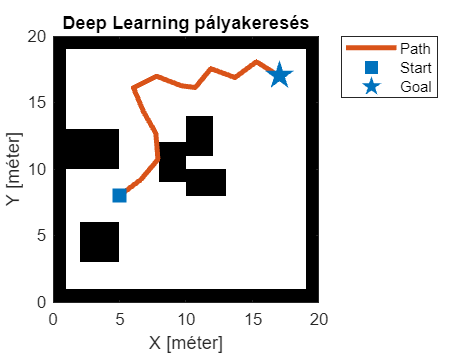

%DL Setup
%We loaded the previously trained deep learning algorithm, and now we are
%going to solve this map
ss = stateSpaceSE2;
ss.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];

stateSamplerDL = stateSamplerMPNET(ss,mpnet);

start = robot_pose;
goal = goal_pose;


stateSamplerDL.Environment = omap;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateValidator = validatorOccupancyMap(ss,Map=omap);
stateValidator.ValidationDistance = 0.1;

plannerDLSampling = plannerRRTStar(ss,stateValidator,MaxConnectionDistance=2,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(omap);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
%plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("Deep Learning pályakeresés")
xlabel("X [méter]")
ylabel("Y [méter]")


%Waypoint setup
pathDLSampling.States

ans =     5.0000    8.0000         0
    6.6000    9.2000         0
    7.8907   10.7157   -0.6056
    7.7333   12.6838    0.4041
    6.8090   14.3000   -1.9056
    6.0471   16.1101   -0.7091
    7.7847   16.9772    0.8042
    9.6381   16.2597    0.0972
   10.6947   16.1276    0.9530
   11.8713   17.5419   -1.5275


k = pathDLSampling.States(:,1);
y = pathDLSampling.States(:,2);
z = pathDLSampling.States(:,3);

waypointsData = [k y z];

%waypointsData = pathDLSampling.States;

wf = uavWaypointFollower(UAVType="multirotor", ...
                         TransitionRadius=1, ...
                         Waypoints=waypointsData);

waypointsData

waypointsData =     5.0000    8.0000         0
    6.6000    9.2000         0
    7.8907   10.7157   -0.6056
    7.7333   12.6838    0.4041
    6.8090   14.3000   -1.9056
    6.0471   16.1101   -0.7091
    7.7847   16.9772    0.8042
    9.6381   16.2597    0.0972
   10.6947   16.1276    0.9530
   11.8713   17.5419   -1.5275


% Specify lookahead distance for the desired point along obstacle-free
% direction, and for the waypoint follower. 
lookaheadOA = 2;
lookaheadWF = 4;

uavPose(1:3)

ans =      8
     5
    -5


% Set up UAV initial state. The UAV state space is position, linear velocity,
% attitude Euler angles, angular velocity, thrust and integral error.
uavPosition = uavPose(1:3)

uavPosition =      8
     5
    -5



uavOrientation = eul2quat(uavPose(4:6)')';
intErr = [0;0;0];
initialState = [uavPosition(1); uavPosition(2); uavPosition(3); ...
                0; 0; 0; uavPose(4); 0; 0; 0; 0; 0; 0; intErr];

% Set the PID controller parameters.
kp = 15;
kd = 12;
ki = 0.005;
kyaw = 10;

% Set up simulation start time and integration interval.
tStart = 0;
tStep = 0.1;

% Solution time points.
hStep = tStep/10;

% Number of iterations.
numIter = 50;

% Store time and states.
tTotal = zeros(numIter*(tStep/hStep+1),1);

% Number of states is equal to the number of model states plus
% integral error.
numStates = numel(model.state)+3;
states = zeros(numIter*(tStep/hStep+1),numStates);


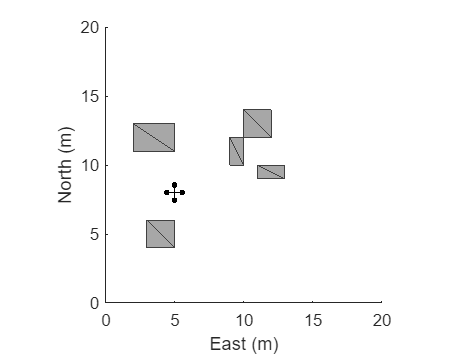

%Figure setup
figure(1)
[ax,plotFrames] = show3D(scene);
%ax.Children(end).LineStyle = "none";
xlim(ax,[0 20])
ylim(ax,[0 20])
zlim(ax,[0 20])
view(ax,2)
%axis(ax,"equal")
hold(ax,"on")

setup(scene)

ans =     8.0000
    5.0000
   -5.0000
    1.5708


targetPosition =     6.2206
    8.9155
         0


desiredDirection =    -0.8426
    0.5368
    0.0436


desiredYaw = 2.5744

status = uint8
0

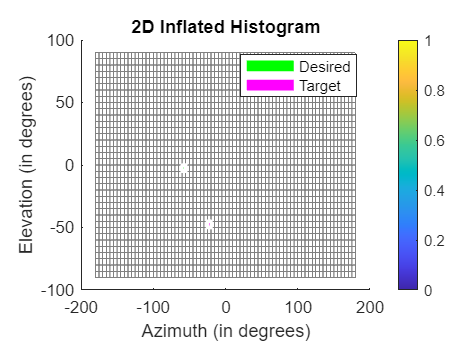

desiredPosition =     6.3148
    6.0736
   -4.9128


s =     8.0000
    5.0000
   -5.0000
         0
         0
         0
    1.5708
         0
         0
         0


s =     8.0000
    5.0000
   -5.0000
         0
         0
    0.0000
    1.5708
         0
         0
    0.0000


s =     8.0000
    5.0000
   -5.0000
         0
         0
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0000


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0000


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0000


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0000


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0000


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0001


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0002


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0002


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0006


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0008


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0009


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0028


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0038


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0000
    1.5708
   -0.0000
    0.0000
    0.0047


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0001
    1.5708
   -0.0000
    0.0000
    0.0142


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0001
    1.5708
   -0.0000
    0.0000
    0.0190


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0002
    1.5708
   -0.0000
    0.0000
    0.0237


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0003
    1.5708
   -0.0000
    0.0000
    0.0459


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0003
    1.5708
   -0.0000
    0.0000
    0.0569


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0004
    1.5708
   -0.0000
    0.0000
    0.0680


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0006
    1.5708
   -0.0000
    0.0000
    0.1001


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0007
    1.5709
   -0.0000
    0.0000
    0.1161


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0007
    1.5709
   -0.0000
    0.0000
    0.1321


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0009
    1.5709
   -0.0000
    0.0000
    0.1733


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0010
    1.5710
   -0.0000
    0.0000
    0.1938


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0011
    1.5710
   -0.0000
    0.0000
    0.2143


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0012
    1.5711
   -0.0000
    0.0000
    0.2634


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0013
    1.5711
   -0.0000
    0.0000
    0.2876


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0014
    1.5712
   -0.0000
    0.0000
    0.3121


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0015
    1.5713
   -0.0000
    0.0000
    0.3702


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0016
    1.5714
   -0.0001
    0.0001
    0.3988


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0016
    1.5715
   -0.0001
    0.0001
    0.4277


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0018
    1.5717
   -0.0001
    0.0001
    0.4959


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0018
    1.5718
   -0.0001
    0.0001
    0.5295


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0019
    1.5720
   -0.0001
    0.0001
    0.5634


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0020
    1.5723
   -0.0001
    0.0001
    0.6436


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0020
    1.5725
   -0.0002
    0.0002
    0.6829


s =     8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0020
    1.5726
   -0.0002
    0.0002
    0.7228


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5730
   -0.0002
    0.0002
    0.8183


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5733
   -0.0003
    0.0003
    0.8649


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5735
   -0.0003
    0.0003
    0.9123


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5741
   -0.0004
    0.0004
    1.0292


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5745
   -0.0004
    0.0004
    1.0860


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5748
   -0.0005
    0.0005
    1.1439


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0021
    1.5757
   -0.0006
    0.0006
    1.2967


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0020
    1.5762
   -0.0007
    0.0007
    1.3700


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0020
    1.5767
   -0.0008
    0.0008
    1.4455


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0020
    1.5780
   -0.0010
    0.0010
    1.6368


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0019
    1.5787
   -0.0011
    0.0011
    1.7274


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0019
    1.5793
   -0.0012
    0.0012
    1.8215


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0018
    1.5810
   -0.0016
    0.0016
    2.0591


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0017
    1.5820
   -0.0018
    0.0018
    2.1698


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0017
    1.5828
   -0.0020
    0.0020
    2.2862


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0016
    1.5854
   -0.0026
    0.0026
    2.6061


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0015
    1.5867
   -0.0030
    0.0030
    2.7506


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0014
    1.5879
   -0.0034
    0.0034
    2.9059


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0000
    0.0000
    0.0012
    1.5919
   -0.0046
    0.0045
    3.3706


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0011
    1.5940
   -0.0055
    0.0054
    3.5677


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0009
    1.5959
   -0.0062
    0.0061
    3.7899


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0007
    1.5998
   -0.0077
    0.0075
    4.1974


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0006
    1.6017
   -0.0087
    0.0085
    4.3708


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0005
    1.6037
   -0.0095
    0.0093
    4.5655


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0008
    1.5988
   -0.0073
    0.0071
    4.0887


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0007
    1.6002
   -0.0080
    0.0078
    4.2218


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0006
    1.6016
   -0.0086
    0.0084
    4.3661


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0001
    0.0001
    0.0005
    1.6045
   -0.0098
    0.0096
    4.6438


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0002
    0.0002
    0.0004
    1.6059
   -0.0106
    0.0104
    4.7672


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0002
    0.0002
    0.0003
    1.6073
   -0.0113
    0.0110
    4.9013


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0002
    0.0002
    0.0001
    1.6112
   -0.0133
    0.0129
    5.2560


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0003
    0.0002
   -0.0000
    1.6131
   -0.0145
    0.0141
    5.4059


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0003
    0.0003
   -0.0001
    1.6150
   -0.0155
    0.0151
    5.5750


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0003
    0.0003
   -0.0003
    1.6188
   -0.0178
    0.0173
    5.8919


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0004
    0.0004
   -0.0004
    1.6207
   -0.0191
    0.0185
    6.0255


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0004
    0.0004
   -0.0006
    1.6226
   -0.0203
    0.0196
    6.1765


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0003
    0.0003
   -0.0003
    1.6179
   -0.0172
    0.0167
    5.8153


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0004
    0.0003
   -0.0004
    1.6193
   -0.0182
    0.0177
    5.9211


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0004
    0.0004
   -0.0004
    1.6208
   -0.0191
    0.0185
    6.0368


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0005
    0.0004
   -0.0006
    1.6237
   -0.0209
    0.0203
    6.2585


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0005
    0.0005
   -0.0007
    1.6251
   -0.0220
    0.0212
    6.3559


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0005
    0.0005
   -0.0008
    1.6265
   -0.0229
    0.0221
    6.4626


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0006
    0.0006
   -0.0010
    1.6302
   -0.0255
    0.0246
    6.7276


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0007
    0.0006
   -0.0011
    1.6321
   -0.0269
    0.0259
    6.8387


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0007
    0.0007
   -0.0012
    1.6339
   -0.0283
    0.0272
    6.9648


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0009
    0.0008
   -0.0014
    1.6376
   -0.0310
    0.0298
    7.2039


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0009
    0.0009
   -0.0015
    1.6394
   -0.0326
    0.0313
    7.3035


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0010
    0.0009
   -0.0016
    1.6413
   -0.0340
    0.0326
    7.4170


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0011
    0.0010
   -0.0017
    1.6445
   -0.0366
    0.0350
    7.6026


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0012
    0.0011
   -0.0018
    1.6460
   -0.0380
    0.0363
    7.6815


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0013
    0.0012
   -0.0019
    1.6476
   -0.0393
    0.0376
    7.7701


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0014
    0.0013
   -0.0021
    1.6504
   -0.0417
    0.0398
    7.9192


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0015
    0.0013
   -0.0021
    1.6518
   -0.0430
    0.0410
    7.9834


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0015
    0.0014
   -0.0022
    1.6532
   -0.0442
    0.0421
    8.0548


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0017
    0.0015
   -0.0024
    1.6562
   -0.0468
    0.0445
    8.1968


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0018
    0.0016
   -0.0024
    1.6576
   -0.0481
    0.0458
    8.2573


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0018
    0.0017
   -0.0025
    1.6591
   -0.0495
    0.0470
    8.3251


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0020
    0.0018
   -0.0027
    1.6623
   -0.0524
    0.0498
    8.4677


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0021
    0.0019
   -0.0028
    1.6639
   -0.0540
    0.0513
    8.5268


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0022
    0.0020
   -0.0029
    1.6655
   -0.0555
    0.0527
    8.5944


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0024
    0.0022
   -0.0030
    1.6687
   -0.0586
    0.0555
    8.7198


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0026
    0.0023
   -0.0031
    1.6703
   -0.0601
    0.0569
    8.7714


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0027
    0.0024
   -0.0032
    1.6718
   -0.0617
    0.0584
    8.8308


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0029
    0.0026
   -0.0033
    1.6747
   -0.0645
    0.0610
    8.9306


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0030
    0.0027
   -0.0034
    1.6761
   -0.0659
    0.0623
    8.9722


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0031
    0.0028
   -0.0035
    1.6775
   -0.0673
    0.0636
    9.0196


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0033
    0.0030
   -0.0036
    1.6802
   -0.0701
    0.0661
    9.1052


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0035
    0.0031
   -0.0037
    1.6815
   -0.0715
    0.0674
    9.1409


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0036
    0.0032
   -0.0037
    1.6828
   -0.0729
    0.0687
    9.1815


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0038
    0.0034
   -0.0039
    1.6857
   -0.0759
    0.0714
    9.2636


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0040
    0.0035
   -0.0039
    1.6871
   -0.0774
    0.0728
    9.2968


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0041
    0.0036
   -0.0040
    1.6886
   -0.0789
    0.0742
    9.3355


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0044
    0.0039
   -0.0042
    1.6916
   -0.0821
    0.0772
    9.4123


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0046
    0.0040
   -0.0042
    1.6931
   -0.0838
    0.0787
    9.4425


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0047
    0.0041
   -0.0043
    1.6946
   -0.0854
    0.0802
    9.4785


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0050
    0.0044
   -0.0044
    1.6976
   -0.0886
    0.0831
    9.5427


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0052
    0.0045
   -0.0045
    1.6990
   -0.0902
    0.0846
    9.5676


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0053
    0.0046
   -0.0046
    1.7005
   -0.0918
    0.0860
    9.5976


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0057
    0.0049
   -0.0047
    1.7032
   -0.0948
    0.0888
    9.6490


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0058
    0.0050
   -0.0047
    1.7046
   -0.0964
    0.0902
    9.6689


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0060
    0.0052
   -0.0048
    1.7059
   -0.0979
    0.0915
    9.6928


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0063
    0.0054
   -0.0049
    1.7086
   -0.1009
    0.0943
    9.7364


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0065
    0.0056
   -0.0050
    1.7100
   -0.1024
    0.0957
    9.7528


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0067
    0.0057
   -0.0050
    1.7113
   -0.1039
    0.0970
    9.7730


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0070
    0.0060
   -0.0052
    1.7141
   -0.1071
    0.0999
    9.8116


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0072
    0.0062
   -0.0052
    1.7155
   -0.1087
    0.1014
    9.8253


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0074
    0.0063
   -0.0053
    1.7170
   -0.1103
    0.1028
    9.8429


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0078
    0.0067
   -0.0054
    1.7198
   -0.1136
    0.1058
    9.8751


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0081
    0.0068
   -0.0054
    1.7213
   -0.1153
    0.1073
    9.8856


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0083
    0.0070
   -0.0055
    1.7227
   -0.1169
    0.1088
    9.9001


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0087
    0.0073
   -0.0056
    1.7255
   -0.1201
    0.1117
    9.9244


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0089
    0.0075
   -0.0056
    1.7269
   -0.1217
    0.1132
    9.9316


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0091
    0.0077
   -0.0057
    1.7282
   -0.1233
    0.1146
    9.9423


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0096
    0.0080
   -0.0058
    1.7309
   -0.1264
    0.1174
    9.9597


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0098
    0.0082
   -0.0059
    1.7322
   -0.1279
    0.1188
    9.9642


s = 16×1
    8.0000
    5.0000
   -5.0000
   -0.0100
    0.0083
   -0.0059
    1.7335
   -0.1295
    0.1202
    9.9716


s = 16×1
    7.9999
    5.0000
   -5.0000
   -0.0105
    0.0087
   -0.0060
    1.7362
   -0.1326
    0.1231
    9.9837


s = 16×1
    7.9999
    5.0000
   -5.0000
   -0.0107
    0.0089
   -0.0060
    1.7375
   -0.1341
    0.1245
    9.9857


s = 16×1
    7.9999
    5.0000
   -5.0000
   -0.0109
    0.0091
   -0.0061
    1.7389
   -0.1357
    0.1259
    9.9906


s = 16×1
    7.9999
    5.0001
   -5.0000
   -0.0114
    0.0094
   -0.0062
    1.7416
   -0.1389
    0.1288
    9.9978


s = 16×1
    7.9999
    5.0001
   -5.0000
   -0.0117
    0.0096
   -0.0062
    1.7430
   -0.1405
    0.1302
    9.9974


s = 16×1
    7.9999
    5.0001
   -5.0000
   -0.0120
    0.0098
   -0.0062
    1.7443
   -0.1421
    0.1317
    9.9998


s = 16×1
    7.9999
    5.0001
   -5.0000
   -0.0125
    0.0102
   -0.0063
    1.7471
   -0.1453
    0.1346
   10.0018


s = 16×1
    7.9999
    5.0001
   -5.0000
   -0.0128
    0.0104
   -0.0064
    1.7484
   -0.1469
    0.1360
    9.9991


s = 16×1
    7.9999
    5.0001
   -5.0000
   -0.0130
    0.0106
   -0.0064
    1.7498
   -0.1485
    0.1375
    9.9990


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0136
    0.0110
   -0.0065
    1.7525
   -0.1517
    0.1403
    9.9963


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0138
    0.0112
   -0.0065
    1.7538
   -0.1532
    0.1417
    9.9916


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0141
    0.0114
   -0.0066
    1.7551
   -0.1548
    0.1431
    9.9893


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0147
    0.0118
   -0.0066
    1.7577
   -0.1578
    0.1459
    9.9825


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0149
    0.0120
   -0.0067
    1.7590
   -0.1594
    0.1473
    9.9760


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0152
    0.0122
   -0.0067
    1.7603
   -0.1609
    0.1487
    9.9717


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0158
    0.0127
   -0.0068
    1.7629
   -0.1640
    0.1514
    9.9609


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0161
    0.0129
   -0.0068
    1.7642
   -0.1655
    0.1528
    9.9526


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0164
    0.0131
   -0.0068
    1.7655
   -0.1670
    0.1542
    9.9464


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0170
    0.0135
   -0.0069
    1.7682
   -0.1701
    0.1570
    9.9316


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0173
    0.0138
   -0.0069
    1.7695
   -0.1717
    0.1584
    9.9215


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0177
    0.0140
   -0.0069
    1.7708
   -0.1732
    0.1598
    9.9133


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0183
    0.0144
   -0.0070
    1.7734
   -0.1763
    0.1626
    9.8950


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0186
    0.0147
   -0.0070
    1.7747
   -0.1778
    0.1640
    9.8833


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0189
    0.0149
   -0.0070
    1.7760
   -0.1793
    0.1654
    9.8735


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0196
    0.0154
   -0.0071
    1.7786
   -0.1823
    0.1681
    9.8523


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0199
    0.0156
   -0.0071
    1.7799
   -0.1838
    0.1694
    9.8395


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0203
    0.0158
   -0.0071
    1.7812
   -0.1853
    0.1708
    9.8282


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0209
    0.0163
   -0.0071
    1.7837
   -0.1882
    0.1734
    9.8043


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0213
    0.0165
   -0.0072
    1.7850
   -0.1897
    0.1748
    9.7903


s = 16×1
    7.9999
    5.0001
   -5.0001
   -0.0216
    0.0168
   -0.0072
    1.7862
   -0.1912
    0.1761
    9.7778


s = 16×1
    7.9998
    5.0001
   -5.0001
   -0.0223
    0.0173
   -0.0072
    1.7888
   -0.1941
    0.1788
    9.7509


s = 16×1
    7.9998
    5.0001
   -5.0001
   -0.0227
    0.0175
   -0.0072
    1.7900
   -0.1956
    0.1801
    9.7355


s = 16×1
    7.9998
    5.0001
   -5.0001
   -0.0230
    0.0178
   -0.0072
    1.7913
   -0.1970
    0.1814
    9.7216


s = 16×1
    7.9998
    5.0001
   -5.0001
   -0.0238
    0.0182
   -0.0072
    1.7939
   -0.2000
    0.1841
    9.6919


s = 16×1
    7.9998
    5.0001
   -5.0001
   -0.0242
    0.0185
   -0.0073
    1.7951
   -0.2014
    0.1854
    9.6752


s = 16×1
    7.9998
    5.0001
   -5.0001
   -0.0245
    0.0188
   -0.0073
    1.7964
   -0.2029
    0.1867
    9.6599


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0253
    0.0193
   -0.0073
    1.7989
   -0.2058
    0.1893
    9.6280


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0257
    0.0195
   -0.0073
    1.8002
   -0.2072
    0.1906
    9.6104


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0261
    0.0198
   -0.0073
    1.8014
   -0.2086
    0.1919
    9.5940


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0268
    0.0203
   -0.0073
    1.8039
   -0.2114
    0.1945
    9.5603


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0272
    0.0205
   -0.0073
    1.8052
   -0.2128
    0.1958
    9.5420


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0276
    0.0208
   -0.0073
    1.8064
   -0.2142
    0.1970
    9.5248


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0284
    0.0213
   -0.0073
    1.8089
   -0.2170
    0.1996
    9.4893


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0288
    0.0216
   -0.0073
    1.8101
   -0.2184
    0.2008
    9.4701


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0292
    0.0218
   -0.0073
    1.8113
   -0.2197
    0.2021
    9.4520


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0300
    0.0224
   -0.0073
    1.8138
   -0.2225
    0.2046
    9.4144


s = 16×1
    7.9998
    5.0002
   -5.0001
   -0.0304
    0.0226
   -0.0073
    1.8150
   -0.2238
    0.2058
    9.3943


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0309
    0.0229
   -0.0073
    1.8163
   -0.2252
    0.2071
    9.3752


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0317
    0.0234
   -0.0073
    1.8187
   -0.2280
    0.2096
    9.3358


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0321
    0.0237
   -0.0072
    1.8200
   -0.2293
    0.2108
    9.3149


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0326
    0.0240
   -0.0072
    1.8212
   -0.2306
    0.2121
    9.2949


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0334
    0.0245
   -0.0072
    1.8236
   -0.2333
    0.2145
    9.2542


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0339
    0.0248
   -0.0072
    1.8248
   -0.2346
    0.2157
    9.2328


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0343
    0.0251
   -0.0072
    1.8261
   -0.2359
    0.2169
    9.2122


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0352
    0.0256
   -0.0072
    1.8285
   -0.2386
    0.2193
    9.1704


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0356
    0.0259
   -0.0071
    1.8297
   -0.2398
    0.2205
    9.1485


s = 16×1
    7.9997
    5.0002
   -5.0001
   -0.0361
    0.0262
   -0.0071
    1.8309
   -0.2411
    0.2217
    9.1274


s = 16×1
    7.9997
    5.0003
   -5.0001
   -0.0370
    0.0268
   -0.0071
    1.8333
   -0.2437
    0.2241
    9.0844


s = 16×1
    7.9997
    5.0003
   -5.0001
   -0.0374
    0.0270
   -0.0071
    1.8345
   -0.2450
    0.2252
    9.0620


s = 16×1
    7.9997
    5.0003
   -5.0001
   -0.0379
    0.0273
   -0.0070
    1.8357
   -0.2462
    0.2264
    9.0403


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0388
    0.0279
   -0.0070
    1.8381
   -0.2488
    0.2287
    8.9959


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0393
    0.0282
   -0.0070
    1.8392
   -0.2500
    0.2299
    8.9729


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0398
    0.0285
   -0.0070
    1.8404
   -0.2513
    0.2310
    8.9506


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0407
    0.0290
   -0.0069
    1.8428
   -0.2538
    0.2334
    8.9052


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0412
    0.0293
   -0.0069
    1.8440
   -0.2550
    0.2345
    8.8818


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0417
    0.0296
   -0.0069
    1.8452
   -0.2562
    0.2356
    8.8590


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0427
    0.0302
   -0.0068
    1.8476
   -0.2587
    0.2379
    8.8129


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0431
    0.0305
   -0.0068
    1.8487
   -0.2599
    0.2390
    8.7892


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0436
    0.0308
   -0.0067
    1.8499
   -0.2611
    0.2401
    8.7661


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0446
    0.0313
   -0.0067
    1.8522
   -0.2635
    0.2423
    8.7193


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0451
    0.0316
   -0.0066
    1.8534
   -0.2646
    0.2434
    8.6954


s = 16×1
    7.9996
    5.0003
   -5.0001
   -0.0456
    0.0319
   -0.0066
    1.8546
   -0.2658
    0.2445
    8.6720


s = 16×1
    7.9995
    5.0004
   -5.0001
   -0.0466
    0.0325
   -0.0065
    1.8569
   -0.2682
    0.2467
    8.6245


s = 16×1
    7.9995
    5.0004
   -5.0001
   -0.0471
    0.0328
   -0.0065
    1.8581
   -0.2693
    0.2478
    8.6003


s = 16×1
    7.9995
    5.0004
   -5.0001
   -0.0477
    0.0331
   -0.0065
    1.8592
   -0.2705
    0.2489
    8.5765


s = 16×1
    7.9995
    5.0004
   -5.0002
   -0.0487
    0.0337
   -0.0064
    1.8615
   -0.2728
    0.2510
    8.5284


s = 16×1
    7.9995
    5.0004
   -5.0002
   -0.0492
    0.0340
   -0.0063
    1.8627
   -0.2739
    0.2521
    8.5038


s = 16×1
    7.9995
    5.0004
   -5.0002
   -0.0497
    0.0343
   -0.0063
    1.8638
   -0.2751
    0.2531
    8.4797


s = 16×1
    7.9995
    5.0004
   -5.0002
   -0.0508
    0.0349
   -0.0062
    1.8662
   -0.2773
    0.2553
    8.4311


s = 16×1
    7.9995
    5.0004
   -5.0002
   -0.0513
    0.0352
   -0.0062
    1.8673
   -0.2784
    0.2563
    8.4064


s = 16×1
    7.9995
    5.0004
   -5.0002
   -0.0519
    0.0355
   -0.0061
    1.8684
   -0.2795
    0.2573
    8.3820


s = 16×1
    7.9994
    5.0004
   -5.0002
   -0.0529
    0.0361
   -0.0060
    1.8707
   -0.2817
    0.2594
    8.3331


s = 16×1
    7.9994
    5.0004
   -5.0002
   -0.0535
    0.0364
   -0.0060
    1.8719
   -0.2828
    0.2604
    8.3083


s = 16×1
    7.9994
    5.0004
   -5.0002
   -0.0540
    0.0367
   -0.0059
    1.8730
   -0.2839
    0.2615
    8.2838


s = 16×1
    7.9994
    5.0004
   -5.0002
   -0.0551
    0.0373
   -0.0059
    1.8753
   -0.2861
    0.2635
    8.2346


s = 16×1
    7.9994
    5.0004
   -5.0002
   -0.0556
    0.0376
   -0.0058
    1.8764
   -0.2871
    0.2645
    8.2098


s = 16×1
    7.9994
    5.0005
   -5.0002
   -0.0562
    0.0379
   -0.0058
    1.8775
   -0.2882
    0.2655
    8.1852


s = 16×1
    7.9994
    5.0005
   -5.0002
   -0.0573
    0.0385
   -0.0056
    1.8798
   -0.2903
    0.2675
    8.1356


s = 16×1
    7.9994
    5.0005
   -5.0002
   -0.0579
    0.0388
   -0.0056
    1.8809
   -0.2913
    0.2685
    8.1106


s = 16×1
    7.9994
    5.0005
   -5.0002
   -0.0584
    0.0391
   -0.0055
    1.8820
   -0.2924
    0.2695
    8.0859


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0595
    0.0397
   -0.0054
    1.8843
   -0.2945
    0.2714
    8.0360


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0601
    0.0400
   -0.0054
    1.8854
   -0.2955
    0.2724
    8.0110


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0607
    0.0403
   -0.0053
    1.8865
   -0.2965
    0.2734
    7.9861


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0618
    0.0409
   -0.0052
    1.8887
   -0.2985
    0.2753
    7.9361


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0624
    0.0412
   -0.0051
    1.8899
   -0.2995
    0.2762
    7.9111


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0630
    0.0415
   -0.0051
    1.8910
   -0.3005
    0.2772
    7.8862


s = 16×1
    7.9993
    5.0005
   -5.0002
   -0.0641
    0.0422
   -0.0050
    1.8932
   -0.3025
    0.2791
    7.8362


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0647
    0.0425
   -0.0049
    1.8943
   -0.3035
    0.2800
    7.8112


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0653
    0.0428
   -0.0048
    1.8954
   -0.3044
    0.2809
    7.7863


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0665
    0.0434
   -0.0047
    1.8976
   -0.3064
    0.2828
    7.7363


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0671
    0.0437
   -0.0046
    1.8987
   -0.3073
    0.2837
    7.7113


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0677
    0.0440
   -0.0046
    1.8998
   -0.3083
    0.2846
    7.6865


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0689
    0.0446
   -0.0044
    1.9020
   -0.3102
    0.2864
    7.6365


s = 16×1
    7.9992
    5.0006
   -5.0002
   -0.0695
    0.0449
   -0.0044
    1.9030
   -0.3111
    0.2873
    7.6115


s = 16×1
    7.9991
    5.0006
   -5.0002
   -0.0701
    0.0452
   -0.0043
    1.9041
   -0.3120
    0.2882
    7.5866


s = 16×1
    7.9991
    5.0006
   -5.0002
   -0.0713
    0.0458
   -0.0042
    1.9063
   -0.3139
    0.2900
    7.5366


s = 16×1
    7.9991
    5.0006
   -5.0002
   -0.0719
    0.0461
   -0.0041
    1.9074
   -0.3148
    0.2909
    7.5117


s = 16×1
    7.9991
    5.0006
   -5.0002
   -0.0725
    0.0465
   -0.0040
    1.9085
   -0.3157
    0.2918
    7.4869


s = 16×1
    7.9991
    5.0007
   -5.0002
   -0.0738
    0.0471
   -0.0039
    1.9106
   -0.3175
    0.2935
    7.4371


s = 16×1
    7.9991
    5.0007
   -5.0002
   -0.0744
    0.0474
   -0.0038
    1.9117
   -0.3184
    0.2944
    7.4123


s = 16×1
    7.9990
    5.0007
   -5.0002
   -0.0750
    0.0477
   -0.0037
    1.9128
   -0.3193
    0.2952
    7.3875


s = 16×1
    7.9990
    5.0007
   -5.0002
   -0.0763
    0.0483
   -0.0036
    1.9149
   -0.3210
    0.2969
    7.3379


s = 16×1
    7.9990
    5.0007
   -5.0002
   -0.0769
    0.0486
   -0.0035
    1.9160
   -0.3219
    0.2978
    7.3132


s = 16×1
    7.9990
    5.0007
   -5.0002
   -0.0775
    0.0489
   -0.0034
    1.9171
   -0.3227
    0.2986
    7.2885


s = 16×1
    7.9990
    5.0007
   -5.0002
   -0.0788
    0.0495
   -0.0033
    1.9192
   -0.3245
    0.3003
    7.2392


s = 16×1
    7.9990
    5.0007
   -5.0002
   -0.0794
    0.0498
   -0.0032
    1.9202
   -0.3253
    0.3011
    7.2146


s = 16×1
    7.9989
    5.0007
   -5.0002
   -0.0801
    0.0502
   -0.0031
    1.9213
   -0.3261
    0.3019
    7.1900


s = 16×1
    7.9989
    5.0008
   -5.0002
   -0.0814
    0.0508
   -0.0030
    1.9234
   -0.3278
    0.3036
    7.1408


s = 16×1
    7.9989
    5.0008
   -5.0002
   -0.0820
    0.0511
   -0.0029
    1.9245
   -0.3286
    0.3044
    7.1164


s = 16×1
    7.9989
    5.0008
   -5.0002
   -0.0827
    0.0514
   -0.0028
    1.9255
   -0.3295
    0.3052
    7.0919


s = 16×1
    7.9989
    5.0008
   -5.0002
   -0.0839
    0.0520
   -0.0026
    1.9276
   -0.3311
    0.3068
    7.0430


s = 16×1
    7.9989
    5.0008
   -5.0002
   -0.0846
    0.0523
   -0.0025
    1.9287
   -0.3319
    0.3076
    7.0187


s = 16×1
    7.9988
    5.0008
   -5.0002
   -0.0853
    0.0526
   -0.0025
    1.9297
   -0.3327
    0.3084
    6.9944


s = 16×1
    7.9988
    5.0008
   -5.0002
   -0.0866
    0.0532
   -0.0023
    1.9318
   -0.3343
    0.3100
    6.9458


s = 16×1
    7.9988
    5.0008
   -5.0002
   -0.0872
    0.0535
   -0.0022
    1.9329
   -0.3351
    0.3107
    6.9217


s = 16×1
    7.9988
    5.0008
   -5.0002
   -0.0879
    0.0538
   -0.0021
    1.9339
   -0.3359
    0.3115
    6.8975


s = 16×1
    7.9988
    5.0009
   -5.0002
   -0.0892
    0.0545
   -0.0019
    1.9360
   -0.3374
    0.3131
    6.8493


s = 16×1
    7.9987
    5.0009
   -5.0002
   -0.0899
    0.0548
   -0.0018
    1.9370
   -0.3382
    0.3138
    6.8254


s = 16×1
    7.9987
    5.0009
   -5.0002
   -0.0906
    0.0551
   -0.0018
    1.9380
   -0.3389
    0.3146
    6.8014


s = 16×1
    7.9987
    5.0009
   -5.0002
   -0.0919
    0.0557
   -0.0016
    1.9400
   -0.3404
    0.3160
    6.7554


s = 16×1
    7.9987
    5.0009
   -5.0002
   -0.0925
    0.0560
   -0.0015
    1.9410
   -0.3411
    0.3167
    6.7326


s = 16×1
    7.9987
    5.0009
   -5.0002
   -0.0932
    0.0563
   -0.0014
    1.9420
   -0.3418
    0.3174
    6.7097


s = 16×1
    7.9986
    5.0009
   -5.0002
   -0.0944
    0.0568
   -0.0012
    1.9439
   -0.3432
    0.3188
    6.6658


s = 16×1
    7.9986
    5.0009
   -5.0002
   -0.0950
    0.0571
   -0.0011
    1.9448
   -0.3438
    0.3195
    6.6441


s = 16×1
    7.9986
    5.0009
   -5.0002
   -0.0957
    0.0574
   -0.0011
    1.9458
   -0.3445
    0.3201
    6.6223


s = 16×1
    7.9986
    5.0010
   -5.0002
   -0.0969
    0.0580
   -0.0009
    1.9477
   -0.3459
    0.3215
    6.5784


s = 16×1
    7.9986
    5.0010
   -5.0002
   -0.0976
    0.0582
   -0.0008
    1.9486
   -0.3465
    0.3222
    6.5566


s = 16×1
    7.9986
    5.0010
   -5.0002
   -0.0982
    0.0585
   -0.0007
    1.9496
   -0.3472
    0.3228
    6.5348


s = 16×1
    7.9985
    5.0010
   -5.0002
   -0.0995
    0.0591
   -0.0005
    1.9515
   -0.3485
    0.3242
    6.4907


s = 16×1
    7.9985
    5.0010
   -5.0002
   -0.1002
    0.0594
   -0.0004
    1.9524
   -0.3491
    0.3248
    6.4689


s = 16×1
    7.9985
    5.0010
   -5.0002
   -0.1009
    0.0597
   -0.0003
    1.9534
   -0.3498
    0.3255
    6.4470


s = 16×1
    7.9985
    5.0010
   -5.0002
   -0.1023
    0.0603
   -0.0001
    1.9554
   -0.3512
    0.3269
    6.3995


s = 16×1
    7.9984
    5.0010
   -5.0002
   -0.1030
    0.0606
   -0.0000
    1.9565
   -0.3519
    0.3276
    6.3761


s = 16×1
    7.9984
    5.0011
   -5.0002
   -0.1037
    0.0609
    0.0001
    1.9575
   -0.3526
    0.3283
    6.3525


s = 16×1
    7.9984
    5.0011
   -5.0002
   -0.1052
    0.0615
    0.0003
    1.9596
   -0.3540
    0.3297
    6.3040


s = 16×1
    7.9984
    5.0011
   -5.0002
   -0.1060
    0.0619
    0.0004
    1.9606
   -0.3547
    0.3304
    6.2802


s = 16×1
    7.9984
    5.0011
   -5.0002
   -0.1067
    0.0622
    0.0005
    1.9617
   -0.3554
    0.3311
    6.2561


s = 16×1
    7.9983
    5.0011
   -5.0002
   -0.1082
    0.0628
    0.0007
    1.9637
   -0.3567
    0.3325
    6.2101


s = 16×1
    7.9983
    5.0011
   -5.0002
   -0.1089
    0.0631
    0.0008
    1.9647
   -0.3573
    0.3331
    6.1874


s = 16×1
    7.9983
    5.0011
   -5.0002
   -0.1096
    0.0634
    0.0009
    1.9657
   -0.3579
    0.3338
    6.1646


s = 16×1
    7.9983
    5.0012
   -5.0002
   -0.1110
    0.0640
    0.0011
    1.9676
   -0.3592
    0.3350
    6.1215


s = 16×1
    7.9982
    5.0012
   -5.0002
   -0.1117
    0.0643
    0.0012
    1.9685
   -0.3597
    0.3356
    6.1003


s = 16×1
    7.9982
    5.0012
   -5.0002
   -0.1124
    0.0646
    0.0013
    1.9695
   -0.3603
    0.3363
    6.0789


s = 16×1
    7.9982
    5.0012
   -5.0002
   -0.1139
    0.0652
    0.0015
    1.9716
   -0.3617
    0.3376
    6.0313


s = 16×1
    7.9982
    5.0012
   -5.0002
   -0.1147
    0.0655
    0.0017
    1.9726
   -0.3623
    0.3383
    6.0079


s = 16×1
    7.9981
    5.0012
   -5.0002
   -0.1155
    0.0658
    0.0018
    1.9737
   -0.3629
    0.3390
    5.9843


s = 16×1
    7.9981
    5.0012
   -5.0002
   -0.1172
    0.0665
    0.0020
    1.9760
   -0.3643
    0.3404
    5.9327


s = 16×1
    7.9981
    5.0013
   -5.0002
   -0.1181
    0.0669
    0.0022
    1.9771
   -0.3650
    0.3411
    5.9074


s = 16×1
    7.9980
    5.0013
   -5.0002
   -0.1190
    0.0672
    0.0023
    1.9783
   -0.3657
    0.3418
    5.8818


s = 16×1
    7.9980
    5.0013
   -5.0002
   -0.1206
    0.0679
    0.0025
    1.9804
   -0.3670
    0.3432
    5.8334


s = 16×1
    7.9980
    5.0013
   -5.0002
   -0.1215
    0.0682
    0.0026
    1.9815
   -0.3676
    0.3438
    5.8096


s = 16×1
    7.9980
    5.0013
   -5.0002
   -0.1223
    0.0685
    0.0028
    1.9826
   -0.3682
    0.3445
    5.7856


s = 16×1
    7.9979
    5.0013
   -5.0002
   -0.1237
    0.0691
    0.0030
    1.9844
   -0.3693
    0.3456
    5.7456


s = 16×1
    7.9979
    5.0014
   -5.0002
   -0.1244
    0.0694
    0.0031
    1.9853
   -0.3698
    0.3461
    5.7259


s = 16×1
    7.9979
    5.0014
   -5.0002
   -0.1251
    0.0696
    0.0032
    1.9862
   -0.3703
    0.3467
    5.7060


s = 16×1
    7.9979
    5.0014
   -5.0002
   -0.1265
    0.0702
    0.0034
    1.9879
   -0.3713
    0.3477
    5.6685


s = 16×1
    7.9978
    5.0014
   -5.0002
   -0.1271
    0.0704
    0.0035
    1.9887
   -0.3717
    0.3482
    5.6500


s = 16×1
    7.9978
    5.0014
   -5.0002
   -0.1278
    0.0707
    0.0036
    1.9895
   -0.3722
    0.3487
    5.6313


s = 16×1
    7.9978
    5.0014
   -5.0002
   -0.1293
    0.0713
    0.0038
    1.9915
   -0.3733
    0.3499
    5.5893


s = 16×1
    7.9978
    5.0014
   -5.0002
   -0.1301
    0.0716
    0.0040
    1.9924
   -0.3738
    0.3504
    5.5687


s = 16×1
    7.9977
    5.0014
   -5.0002
   -0.1309
    0.0719
    0.0041
    1.9934
   -0.3743
    0.3510
    5.5478


s = 16×1
    7.9977
    5.0015
   -5.0002
   -0.1326
    0.0725
    0.0043
    1.9955
   -0.3755
    0.3522
    5.5020


s = 16×1
    7.9977
    5.0015
   -5.0002
   -0.1334
    0.0728
    0.0045
    1.9965
   -0.3760
    0.3528
    5.4796


s = 16×1
    7.9976
    5.0015
   -5.0002
   -0.1343
    0.0731
    0.0046
    1.9975
   -0.3766
    0.3534
    5.4569


s = 16×1
    7.9976
    5.0015
   -5.0002
   -0.1359
    0.0737
    0.0048
    1.9995
   -0.3776
    0.3545
    5.4144


s = 16×1
    7.9976
    5.0015
   -5.0002
   -0.1367
    0.0740
    0.0050
    2.0005
   -0.3781
    0.3551
    5.3936


s = 16×1
    7.9975
    5.0016
   -5.0002
   -0.1375
    0.0743
    0.0051
    2.0014
   -0.3787
    0.3556
    5.3726


s = 16×1
    7.9975
    5.0016
   -5.0002
   -0.1390
    0.0749
    0.0053
    2.0032
   -0.3796
    0.3566
    5.3351


s = 16×1
    7.9975
    5.0016
   -5.0002
   -0.1397
    0.0751
    0.0054
    2.0040
   -0.3800
    0.3571
    5.3167


s = 16×1
    7.9975
    5.0016
   -5.0002
   -0.1404
    0.0754
    0.0055
    2.0049
   -0.3804
    0.3576
    5.2980


s = 16×1
    7.9974
    5.0016
   -5.0002
   -0.1419
    0.0759
    0.0058
    2.0067
   -0.3813
    0.3585
    5.2610


s = 16×1
    7.9974
    5.0016
   -5.0002
   -0.1426
    0.0762
    0.0059
    2.0075
   -0.3818
    0.3590
    5.2428


s = 16×1
    7.9974
    5.0016
   -5.0002
   -0.1434
    0.0765
    0.0060
    2.0084
   -0.3822
    0.3595
    5.2244


s = 16×1
    7.9973
    5.0017
   -5.0002
   -0.1450
    0.0770
    0.0062
    2.0103
   -0.3831
    0.3605
    5.1844


s = 16×1
    7.9973
    5.0017
   -5.0002
   -0.1458
    0.0773
    0.0064
    2.0112
   -0.3836
    0.3610
    5.1648


s = 16×1
    7.9973
    5.0017
   -5.0002
   -0.1466
    0.0776
    0.0065
    2.0121
   -0.3840
    0.3615
    5.1449


s = 16×1
    7.9972
    5.0017
   -5.0002
   -0.1483
    0.0782
    0.0067
    2.0141
   -0.3850
    0.3625
    5.1039


s = 16×1
    7.9972
    5.0017
   -5.0002
   -0.1492
    0.0785
    0.0069
    2.0151
   -0.3855
    0.3630
    5.0838


s = 16×1
    7.9972
    5.0017
   -5.0002
   -0.1500
    0.0788
    0.0070
    2.0160
   -0.3859
    0.3636
    5.0635


s = 16×1
    7.9971
    5.0018
   -5.0002
   -0.1516
    0.0794
    0.0073
    2.0179
   -0.3868
    0.3645
    5.0254


s = 16×1
    7.9971
    5.0018
   -5.0002
   -0.1524
    0.0796
    0.0074
    2.0188
   -0.3872
    0.3650
    5.0067


s = 16×1
    7.9971
    5.0018
   -5.0002
   -0.1532
    0.0799
    0.0075
    2.0197
   -0.3876
    0.3655
    4.9878


s = 16×1
    7.9970
    5.0018
   -5.0002
   -0.1548
    0.0804
    0.0077
    2.0214
   -0.3884
    0.3663
    4.9523


s = 16×1
    7.9970
    5.0018
   -5.0002
   -0.1555
    0.0807
    0.0079
    2.0222
   -0.3888
    0.3668
    4.9350


s = 16×1
    7.9970
    5.0018
   -5.0002
   -0.1563
    0.0810
    0.0080
    2.0231
   -0.3892
    0.3672
    4.9174


s = 16×1
    7.9969
    5.0019
   -5.0002
   -0.1579
    0.0815
    0.0082
    2.0248
   -0.3900
    0.3681
    4.8817


s = 16×1
    7.9969
    5.0019
   -5.0002
   -0.1587
    0.0818
    0.0083
    2.0257
   -0.3904
    0.3685
    4.8643


s = 16×1
    7.9969
    5.0019
   -5.0002
   -0.1595
    0.0820
    0.0085
    2.0266
   -0.3908
    0.3690
    4.8466


s = 16×1
    7.9968
    5.0019
   -5.0002
   -0.1611
    0.0826
    0.0087
    2.0284
   -0.3916
    0.3699
    4.8093


s = 16×1
    7.9968
    5.0019
   -5.0002
   -0.1620
    0.0829
    0.0089
    2.0293
   -0.3920
    0.3703
    4.7911


s = 16×1
    7.9968
    5.0020
   -5.0001
   -0.1628
    0.0831
    0.0090
    2.0302
   -0.3924
    0.3708
    4.7727


s = 16×1
    7.9967
    5.0020
   -5.0001
   -0.1645
    0.0837
    0.0093
    2.0321
   -0.3931
    0.3717
    4.7357


s = 16×1
    7.9967
    5.0020
   -5.0001
   -0.1654
    0.0840
    0.0094
    2.0330
   -0.3935
    0.3721
    4.7177


s = 16×1
    7.9967
    5.0020
   -5.0001
   -0.1662
    0.0842
    0.0095
    2.0339
   -0.3939
    0.3725
    4.6994


s = 16×1
    7.9966
    5.0020
   -5.0001
   -0.1679
    0.0848
    0.0098
    2.0356
   -0.3946
    0.3734
    4.6646


s = 16×1
    7.9966
    5.0021
   -5.0001
   -0.1687
    0.0850
    0.0099
    2.0365
   -0.3950
    0.3738
    4.6476


s = 16×1
    7.9966
    5.0021
   -5.0001
   -0.1695
    0.0853
    0.0100
    2.0374
   -0.3954
    0.3742
    4.6304


s = 16×1
    7.9965
    5.0021
   -5.0001
   -0.1711
    0.0858
    0.0103
    2.0390
   -0.3961
    0.3750
    4.5970


s = 16×1
    7.9965
    5.0021
   -5.0001
   -0.1719
    0.0861
    0.0104
    2.0399
   -0.3964
    0.3754
    4.5807


s = 16×1
    7.9964
    5.0021
   -5.0001
   -0.1727
    0.0863
    0.0105
    2.0407
   -0.3967
    0.3758
    4.5641


s = 16×1
    7.9964
    5.0021
   -5.0001
   -0.1744
    0.0868
    0.0108
    2.0424
   -0.3974
    0.3766
    4.5305


s = 16×1
    7.9964
    5.0022
   -5.0001
   -0.1752
    0.0871
    0.0109
    2.0433
   -0.3977
    0.3770
    4.5140


s = 16×1
    7.9963
    5.0022
   -5.0001
   -0.1760
    0.0874
    0.0110
    2.0441
   -0.3981
    0.3774
    4.4973


s = 16×1
    7.9963
    5.0022
   -5.0001
   -0.1777
    0.0879
    0.0113
    2.0459
   -0.3988
    0.3782
    4.4631


s = 16×1
    7.9962
    5.0022
   -5.0001
   -0.1786
    0.0881
    0.0114
    2.0468
   -0.3991
    0.3786
    4.4464


s = 16×1
    7.9962
    5.0022
   -5.0001
   -0.1794
    0.0884
    0.0116
    2.0477
   -0.3994
    0.3789
    4.4295


s = 16×1
    7.9962
    5.0023
   -5.0001
   -0.1812
    0.0889
    0.0119
    2.0494
   -0.4001
    0.3797
    4.3960


s = 16×1
    7.9961
    5.0023
   -5.0001
   -0.1820
    0.0892
    0.0120
    2.0503
   -0.4004
    0.3801
    4.3797


s = 16×1
    7.9961
    5.0023
   -5.0001
   -0.1829
    0.0895
    0.0121
    2.0511
   -0.4008
    0.3805
    4.3631


s = 16×1
    7.9960
    5.0023
   -5.0001
   -0.1846
    0.0900
    0.0124
    2.0528
   -0.4014
    0.3812
    4.3311


s = 16×1
    7.9960
    5.0023
   -5.0001
   -0.1854
    0.0902
    0.0125
    2.0536
   -0.4017
    0.3816
    4.3155


s = 16×1
    7.9960
    5.0024
   -5.0001
   -0.1862
    0.0905
    0.0126
    2.0545
   -0.4020
    0.3819
    4.2997


s = 16×1
    7.9959
    5.0024
   -5.0001
   -0.1879
    0.0910
    0.0129
    2.0561
   -0.4026
    0.3827
    4.2685


s = 16×1
    7.9959
    5.0024
   -5.0001
   -0.1887
    0.0912
    0.0130
    2.0570
   -0.4029
    0.3830
    4.2532


s = 16×1
    7.9959
    5.0024
   -5.0001
   -0.1896
    0.0914
    0.0132
    2.0578
   -0.4032
    0.3834
    4.2378


s = 16×1
    7.9958
    5.0024
   -5.0001
   -0.1913
    0.0919
    0.0134
    2.0595
   -0.4038
    0.3841
    4.2065


s = 16×1
    7.9958
    5.0025
   -5.0001
   -0.1921
    0.0922
    0.0136
    2.0603
   -0.4040
    0.3844
    4.1912


s = 16×1
    7.9957
    5.0025
   -5.0001
   -0.1930
    0.0924
    0.0137
    2.0611
   -0.4043
    0.3848
    4.1757


s = 16×1
    7.9957
    5.0025
   -5.0001
   -0.1947
    0.0929
    0.0140
    2.0628
   -0.4049
    0.3855
    4.1444


s = 16×1
    7.9956
    5.0025
   -5.0001
   -0.1956
    0.0932
    0.0141
    2.0637
   -0.4052
    0.3858
    4.1292


s = 16×1
    7.9956
    5.0025
   -5.0001
   -0.1965
    0.0934
    0.0142
    2.0645
   -0.4055
    0.3862
    4.1136


s = 16×1
    7.9955
    5.0026
   -5.0001
   -0.1982
    0.0939
    0.0145
    2.0662
   -0.4060
    0.3868
    4.0832


s = 16×1
    7.9955
    5.0026
   -5.0001
   -0.1991
    0.0942
    0.0146
    2.0670
   -0.4063
    0.3872
    4.0683


s = 16×1
    7.9955
    5.0026
   -5.0001
   -0.2000
    0.0944
    0.0148
    2.0678
   -0.4066
    0.3875
    4.0532


s = 16×1
    7.9954
    5.0026
   -5.0001
   -0.2017
    0.0949
    0.0150
    2.0695
   -0.4071
    0.3882
    4.0238


s = 16×1
    7.9954
    5.0026
   -5.0001
   -0.2025
    0.0951
    0.0152
    2.0703
   -0.4074
    0.3885
    4.0094


s = 16×1
    7.9954
    5.0027
   -5.0001
   -0.2034
    0.0954
    0.0153
    2.0711
   -0.4076
    0.3888
    3.9949


s = 16×1
    7.9953
    5.0027
   -5.0000
   -0.2051
    0.0958
    0.0156
    2.0727
   -0.4082
    0.3894
    3.9659


s = 16×1
    7.9953
    5.0027
   -5.0000
   -0.2060
    0.0961
    0.0157
    2.0735
   -0.4084
    0.3897
    3.9518


s = 16×1
    7.9952
    5.0027
   -5.0000
   -0.2068
    0.0963
    0.0158
    2.0743
   -0.4087
    0.3901
    3.9375


s = 16×1
    7.9952
    5.0027
   -5.0000
   -0.2086
    0.0968
    0.0161
    2.0759
   -0.4092
    0.3907
    3.9086


s = 16×1
    7.9951
    5.0028
   -5.0000
   -0.2095
    0.0970
    0.0162
    2.0768
   -0.4094
    0.3910
    3.8945


s = 16×1
    7.9951
    5.0028
   -5.0000
   -0.2104
    0.0973
    0.0164
    2.0776
   -0.4097
    0.3913
    3.8802


s = 16×1
    7.9950
    5.0028
   -5.0000
   -0.2121
    0.0977
    0.0166
    2.0792
   -0.4101
    0.3919
    3.8517


s = 16×1
    7.9950
    5.0028
   -5.0000
   -0.2130
    0.0980
    0.0168
    2.0800
   -0.4104
    0.3922
    3.8378


s = 16×1
    7.9949
    5.0028
   -5.0000
   -0.2139
    0.0982
    0.0169
    2.0808
   -0.4106
    0.3925
    3.8236


s = 16×1
    7.9949
    5.0029
   -5.0000
   -0.2157
    0.0987
    0.0172
    2.0824
   -0.4111
    0.3931
    3.7958


s = 16×1
    7.9948
    5.0029
   -5.0000
   -0.2165
    0.0989
    0.0173
    2.0832
   -0.4113
    0.3934
    3.7823


s = 16×1
    7.9948
    5.0029
   -5.0000
   -0.2174
    0.0991
    0.0175
    2.0840
   -0.4116
    0.3937
    3.7685


s = 16×1
    7.9947
    5.0029
   -5.0000
   -0.2192
    0.0996
    0.0177
    2.0856
   -0.4120
    0.3943
    3.7414


s = 16×1
    7.9947
    5.0029
   -5.0000
   -0.2201
    0.0998
    0.0179
    2.0864
   -0.4122
    0.3945
    3.7282


s = 16×1
    7.9947
    5.0030
   -5.0000
   -0.2209
    0.1000
    0.0180
    2.0872
   -0.4124
    0.3948
    3.7148


s = 16×1
    7.9946
    5.0030
   -5.0000
   -0.2227
    0.1005
    0.0183
    2.0887
   -0.4129
    0.3954
    3.6881


s = 16×1
    7.9946
    5.0030
   -5.0000
   -0.2236
    0.1007
    0.0184
    2.0895
   -0.4131
    0.3957
    3.6751


s = 16×1
    7.9945
    5.0030
   -5.0000
   -0.2245
    0.1009
    0.0185
    2.0903
   -0.4133
    0.3959
    3.6619


s = 16×1
    7.9945
    5.0031
   -5.0000
   -0.2263
    0.1014
    0.0188
    2.0919
   -0.4137
    0.3965
    3.6354


s = 16×1
    7.9944
    5.0031
   -5.0000
   -0.2272
    0.1016
    0.0189
    2.0927
   -0.4139
    0.3968
    3.6225


s = 16×1
    7.9944
    5.0031
   -5.0000
   -0.2281
    0.1018
    0.0191
    2.0935
   -0.4142
    0.3970
    3.6094


s = 16×1
    7.9943
    5.0031
   -5.0000
   -0.2299
    0.1022
    0.0194
    2.0950
   -0.4146
    0.3976
    3.5833


s = 16×1
    7.9943
    5.0031
   -5.0000
   -0.2308
    0.1025
    0.0195
    2.0958
   -0.4148
    0.3978
    3.5706


s = 16×1
    7.9942
    5.0032
   -5.0000
   -0.2317
    0.1027
    0.0196
    2.0966
   -0.4150
    0.3981
    3.5577


s = 16×1
    7.9942
    5.0032
   -5.0000
   -0.2335
    0.1031
    0.0199
    2.0981
   -0.4154
    0.3986
    3.5323


s = 16×1
    7.9941
    5.0032
   -5.0000
   -0.2344
    0.1033
    0.0200
    2.0989
   -0.4156
    0.3989
    3.5172


s = 16×1
    7.9941
    5.0032
   -5.0000
   -0.2353
    0.1036
    0.0202
    2.0997
   -0.4158
    0.3991
    3.5038


s = 16×1
    7.9940
    5.0033
   -4.9999
   -0.2368
    0.1039
    0.0204
    2.1010
   -0.4161
    0.3996
    3.4794


s = 16×1
    7.9940
    5.0033
   -4.9999
   -0.2376
    0.1041
    0.0205
    2.1017
   -0.4163
    0.3998
    3.4654


s = 16×1
    7.9939
    5.0033
   -4.9999
   -0.2383
    0.1043
    0.0206
    2.1023
   -0.4164
    0.4000
    3.4527


s = 16×1
    7.9939
    5.0033
   -4.9999
   -0.2400
    0.1047
    0.0209
    2.1037
   -0.4168
    0.4005
    3.4233


s = 16×1
    7.9938
    5.0033
   -4.9999
   -0.2409
    0.1049
    0.0210
    2.1045
   -0.4169
    0.4007
    3.4067


s = 16×1
    7.9938
    5.0034
   -4.9999
   -0.2417
    0.1051
    0.0212
    2.1052
   -0.4171
    0.4009
    3.3914


s = 16×1
    7.9937
    5.0034
   -4.9999
   -0.2437
    0.1055
    0.0215
    2.1069
   -0.4175
    0.4015
    3.3532


s = 16×1
    7.9937
    5.0034
   -4.9999
   -0.2448
    0.1058
    0.0217
    2.1078
   -0.4177
    0.4017
    3.3314


s = 16×1
    7.9936
    5.0034
   -4.9999
   -0.2458
    0.1060
    0.0218
    2.1086
   -0.4179
    0.4020
    3.3116


s = 16×1
    7.9935
    5.0035
   -4.9999
   -0.2478
    0.1065
    0.0221
    2.1103
   -0.4183
    0.4025
    3.2706


s = 16×1
    7.9935
    5.0035
   -4.9999
   -0.2488
    0.1067
    0.0223
    2.1111
   -0.4185
    0.4027
    3.2479


s = 16×1
    7.9934
    5.0035
   -4.9999
   -0.2498
    0.1069
    0.0225
    2.1120
   -0.4187
    0.4030
    3.2267


s = 16×1
    7.9934
    5.0035
   -4.9999
   -0.2515
    0.1073
    0.0227
    2.1134
   -0.4190
    0.4034
    3.1891


s = 16×1
    7.9933
    5.0036
   -4.9999
   -0.2524
    0.1075
    0.0229
    2.1141
   -0.4192
    0.4036
    3.1688


s = 16×1
    7.9933
    5.0036
   -4.9999
   -0.2533
    0.1077
    0.0230
    2.1148
   -0.4193
    0.4038
    3.1495


s = 16×1
    7.9932
    5.0036
   -4.9999
   -0.2549
    0.1081
    0.0233
    2.1162
   -0.4196
    0.4041
    3.1123


s = 16×1
    7.9932
    5.0036
   -4.9999
   -0.2557
    0.1082
    0.0234
    2.1168
   -0.4197
    0.4043
    3.0925


s = 16×1
    7.9931
    5.0036
   -4.9999
   -0.2565
    0.1084
    0.0236
    2.1175
   -0.4199
    0.4045
    3.0736


s = 16×1
    7.9931
    5.0037
   -4.9999
   -0.2584
    0.1088
    0.0238
    2.1190
   -0.4202
    0.4049
    3.0308


s = 16×1
    7.9930
    5.0037
   -4.9999
   -0.2593
    0.1090
    0.0240
    2.1197
   -0.4204
    0.4050
    3.0081


s = 16×1
    7.9930
    5.0037
   -4.9999
   -0.2602
    0.1092
    0.0241
    2.1204
   -0.4205
    0.4052
    2.9864


s = 16×1
    7.9929
    5.0037
   -4.9998
   -0.2621
    0.1096
    0.0245
    2.1221
   -0.4208
    0.4056
    2.9376


s = 16×1
    7.9928
    5.0038
   -4.9998
   -0.2631
    0.1098
    0.0246
    2.1229
   -0.4210
    0.4058
    2.9118


s = 16×1
    7.9928
    5.0038
   -4.9998
   -0.2641
    0.1100
    0.0248
    2.1237
   -0.4212
    0.4060
    2.8870


s = 16×1
    7.9927
    5.0038
   -4.9998
   -0.2660
    0.1104
    0.0251
    2.1252
   -0.4215
    0.4063
    2.8384


s = 16×1
    7.9927
    5.0038
   -4.9998
   -0.2670
    0.1106
    0.0253
    2.1260
   -0.4216
    0.4065
    2.8130


s = 16×1
    7.9926
    5.0039
   -4.9998
   -0.2680
    0.1108
    0.0255
    2.1267
   -0.4218
    0.4067
    2.7884


s = 16×1
    7.9925
    5.0039
   -4.9998
   -0.2697
    0.1112
    0.0258
    2.1281
   -0.4220
    0.4069
    2.7430


s = 16×1
    7.9925
    5.0039
   -4.9998
   -0.2706
    0.1114
    0.0259
    2.1288
   -0.4222
    0.4071
    2.7195


s = 16×1
    7.9924
    5.0039
   -4.9998
   -0.2714
    0.1115
    0.0261
    2.1295
   -0.4223
    0.4072
    2.6966


s = 16×1
    7.9924
    5.0040
   -4.9998
   -0.2732
    0.1119
    0.0263
    2.1308
   -0.4225
    0.4075
    2.6506


s = 16×1
    7.9923
    5.0040
   -4.9998
   -0.2740
    0.1121
    0.0265
    2.1315
   -0.4227
    0.4076
    2.6269


s = 16×1
    7.9923
    5.0040
   -4.9998
   -0.2749
    0.1122
    0.0266
    2.1322
   -0.4228
    0.4077
    2.6037


s = 16×1
    7.9922
    5.0040
   -4.9998
   -0.2767
    0.1126
    0.0270
    2.1336
   -0.4231
    0.4080
    2.5532


s = 16×1
    7.9921
    5.0040
   -4.9998
   -0.2777
    0.1128
    0.0271
    2.1344
   -0.4232
    0.4081
    2.5273


s = 16×1
    7.9921
    5.0041
   -4.9998
   -0.2786
    0.1130
    0.0273
    2.1351
   -0.4233
    0.4082
    2.5019


s = 16×1
    7.9920
    5.0041
   -4.9998
   -0.2805
    0.1134
    0.0276
    2.1366
   -0.4236
    0.4084
    2.4483


s = 16×1
    7.9920
    5.0041
   -4.9998
   -0.2815
    0.1136
    0.0278
    2.1374
   -0.4237
    0.4085
    2.4208


s = 16×1
    7.9919
    5.0041
   -4.9998
   -0.2825
    0.1137
    0.0280
    2.1381
   -0.4239
    0.4086
    2.3938


s = 16×1
    7.9918
    5.0042
   -4.9997
   -0.2843
    0.1141
    0.0283
    2.1395
   -0.4241
    0.4088
    2.3418


s = 16×1
    7.9918
    5.0042
   -4.9997
   -0.2853
    0.1143
    0.0285
    2.1403
   -0.4242
    0.4089
    2.3153


s = 16×1
    7.9917
    5.0042
   -4.9997
   -0.2862
    0.1145
    0.0286
    2.1410
   -0.4243
    0.4090
    2.2892


s = 16×1
    7.9916
    5.0043
   -4.9997
   -0.2879
    0.1148
    0.0289
    2.1423
   -0.4246
    0.4091
    2.2393


s = 16×1
    7.9916
    5.0043
   -4.9997
   -0.2888
    0.1150
    0.0291
    2.1430
   -0.4247
    0.4092
    2.2140


s = 16×1
    7.9915
    5.0043
   -4.9997
   -0.2897
    0.1151
    0.0292
    2.1437
   -0.4248
    0.4093
    2.1890


s = 16×1
    7.9914
    5.0043
   -4.9997
   -0.2915
    0.1155
    0.0296
    2.1450
   -0.4250
    0.4094
    2.1381


s = 16×1
    7.9914
    5.0043
   -4.9997
   -0.2924
    0.1156
    0.0297
    2.1457
   -0.4251
    0.4094
    2.1124


s = 16×1
    7.9914
    5.0044
   -4.9997
   -0.2933
    0.1158
    0.0299
    2.1464
   -0.4252
    0.4095
    2.0869


s = 16×1
    7.9913
    5.0044
   -4.9997
   -0.2952
    0.1162
    0.0302
    2.1478
   -0.4254
    0.4096
    2.0330


s = 16×1
    7.9912
    5.0044
   -4.9997
   -0.2961
    0.1163
    0.0304
    2.1485
   -0.4255
    0.4096
    2.0058


s = 16×1
    7.9912
    5.0044
   -4.9997
   -0.2970
    0.1165
    0.0306
    2.1492
   -0.4257
    0.4097
    1.9788


s = 16×1
    7.9911
    5.0045
   -4.9997
   -0.2989
    0.1169
    0.0309
    2.1506
   -0.4259
    0.4097
    1.9241


s = 16×1
    7.9910
    5.0045
   -4.9997
   -0.2999
    0.1170
    0.0311
    2.1513
   -0.4260
    0.4098
    1.8966


s = 16×1
    7.9910
    5.0045
   -4.9997
   -0.3008
    0.1172
    0.0312
    2.1521
   -0.4261
    0.4098
    1.8692


s = 16×1
    7.9909
    5.0046
   -4.9996
   -0.3027
    0.1175
    0.0316
    2.1534
   -0.4263
    0.4098
    1.8161


s = 16×1
    7.9908
    5.0046
   -4.9996
   -0.3036
    0.1177
    0.0317
    2.1541
   -0.4264
    0.4098
    1.7895


s = 16×1
    7.9908
    5.0046
   -4.9996
   -0.3045
    0.1179
    0.0319
    2.1548
   -0.4265
    0.4098
    1.7630


s = 16×1
    7.9907
    5.0046
   -4.9996
   -0.3063
    0.1182
    0.0322
    2.1561
   -0.4267
    0.4098
    1.7113


s = 16×1
    7.9906
    5.0046
   -4.9996
   -0.3072
    0.1183
    0.0324
    2.1568
   -0.4268
    0.4098
    1.6854


s = 16×1
    7.9906
    5.0047
   -4.9996
   -0.3081
    0.1185
    0.0326
    2.1574
   -0.4268
    0.4098
    1.6595


s = 16×1
    7.9905
    5.0047
   -4.9996
   -0.3099
    0.1188
    0.0329
    2.1588
   -0.4270
    0.4098
    1.6069


s = 16×1
    7.9904
    5.0047
   -4.9996
   -0.3108
    0.1190
    0.0331
    2.1594
   -0.4271
    0.4097
    1.5806


s = 16×1
    7.9904
    5.0047
   -4.9996
   -0.3117
    0.1191
    0.0332
    2.1601
   -0.4272
    0.4097
    1.5543


s = 16×1
    7.9903
    5.0048
   -4.9996
   -0.3136
    0.1195
    0.0336
    2.1615
   -0.4274
    0.4097
    1.5002


s = 16×1
    7.9902
    5.0048
   -4.9996
   -0.3145
    0.1196
    0.0337
    2.1621
   -0.4275
    0.4096
    1.4733


s = 16×1
    7.9902
    5.0048
   -4.9996
   -0.3155
    0.1198
    0.0339
    2.1628
   -0.4276
    0.4096
    1.4463


s = 16×1
    7.9901
    5.0049
   -4.9996
   -0.3173
    0.1201
    0.0342
    2.1642
   -0.4277
    0.4095
    1.3924


s = 16×1
    7.9900
    5.0049
   -4.9996
   -0.3183
    0.1203
    0.0344
    2.1649
   -0.4278
    0.4094
    1.3656


s = 16×1
    7.9900
    5.0049
   -4.9995
   -0.3192
    0.1204
    0.0346
    2.1655
   -0.4279
    0.4094
    1.3388


s = 16×1
    7.9899
    5.0049
   -4.9995
   -0.3211
    0.1207
    0.0349
    2.1669
   -0.4281
    0.4093
    1.2865


s = 16×1
    7.9898
    5.0050
   -4.9995
   -0.3220
    0.1209
    0.0351
    2.1675
   -0.4282
    0.4092
    1.2605


s = 16×1
    7.9898
    5.0050
   -4.9995
   -0.3229
    0.1210
    0.0353
    2.1682
   -0.4282
    0.4091
    1.2344


s = 16×1
    7.9897
    5.0050
   -4.9995
   -0.3247
    0.1213
    0.0356
    2.1695
   -0.4284
    0.4090
    1.1829


s = 16×1
    7.9896
    5.0050
   -4.9995
   -0.3256
    0.1215
    0.0358
    2.1701
   -0.4285
    0.4089
    1.1574


s = 16×1
    7.9895
    5.0051
   -4.9995
   -0.3265
    0.1216
    0.0359
    2.1708
   -0.4285
    0.4088
    1.1317


s = 16×1
    7.9894
    5.0051
   -4.9995
   -0.3283
    0.1219
    0.0363
    2.1721
   -0.4287
    0.4086
    1.0797


s = 16×1
    7.9894
    5.0051
   -4.9995
   -0.3293
    0.1221
    0.0364
    2.1727
   -0.4288
    0.4085
    1.0540


s = 16×1
    7.9893
    5.0051
   -4.9995
   -0.3302
    0.1223
    0.0366
    2.1734
   -0.4288
    0.4084
    1.0281


s = 16×1
    7.9892
    5.0052
   -4.9995
   -0.3320
    0.1226
    0.0370
    2.1747
   -0.4290
    0.4082
    0.9757


s = 16×1
    7.9892
    5.0052
   -4.9995
   -0.3330
    0.1227
    0.0371
    2.1753
   -0.4291
    0.4081
    0.9498


s = 16×1
    7.9891
    5.0052
   -4.9995
   -0.3339
    0.1229
    0.0373
    2.1760
   -0.4291
    0.4079
    0.9238


s = 16×1
    7.9890
    5.0053
   -4.9994
   -0.3358
    0.1232
    0.0376
    2.1773
   -0.4293
    0.4077
    0.8722


s = 16×1
    7.9890
    5.0053
   -4.9994
   -0.3367
    0.1233
    0.0378
    2.1779
   -0.4293
    0.4076
    0.8467


s = 16×1
    7.9889
    5.0053
   -4.9994
   -0.3376
    0.1235
    0.0380
    2.1786
   -0.4294
    0.4074
    0.8211


s = 16×1
    7.9888
    5.0053
   -4.9994
   -0.3395
    0.1238
    0.0383
    2.1799
   -0.4295
    0.4072
    0.7707


s = 16×1
    7.9887
    5.0054
   -4.9994
   -0.3404
    0.1239
    0.0385
    2.1805
   -0.4296
    0.4070
    0.7459


s = 16×1
    7.9887
    5.0054
   -4.9994
   -0.3413
    0.1240
    0.0387
    2.1811
   -0.4297
    0.4069
    0.7209


s = 16×1
    7.9886
    5.0054
   -4.9994
   -0.3431
    0.1243
    0.0390
    2.1824
   -0.4298
    0.4066
    0.6712


s = 16×1
    7.9885
    5.0054
   -4.9994
   -0.3440
    0.1245
    0.0392
    2.1830
   -0.4299
    0.4064
    0.6467


s = 16×1
    7.9885
    5.0055
   -4.9994
   -0.3449
    0.1246
    0.0393
    2.1837
   -0.4299
    0.4062
    0.6220


s = 16×1
    7.9884
    5.0055
   -4.9994
   -0.3468
    0.1249
    0.0397
    2.1849
   -0.4300
    0.4059
    0.5723


s = 16×1
    7.9883
    5.0055
   -4.9994
   -0.3477
    0.1251
    0.0399
    2.1856
   -0.4301
    0.4057
    0.5478


s = 16×1
    7.9882
    5.0055
   -4.9994
   -0.3486
    0.1252
    0.0400
    2.1862
   -0.4302
    0.4056
    0.5231


s = 16×1
    7.9881
    5.0056
   -4.9993
   -0.3505
    0.1255
    0.0404
    2.1875
   -0.4303
    0.4052
    0.4736


s = 16×1
    7.9881
    5.0056
   -4.9993
   -0.3514
    0.1256
    0.0405
    2.1881
   -0.4303
    0.4050
    0.4494


s = 16×1
    7.9880
    5.0056
   -4.9993
   -0.3523
    0.1258
    0.0407
    2.1887
   -0.4304
    0.4048
    0.4248


s = 16×1
    7.9879
    5.0057
   -4.9993
   -0.3542
    0.1261
    0.0411
    2.1900
   -0.4305
    0.4044
    0.3763


s = 16×1
    7.9878
    5.0057
   -4.9993
   -0.3551
    0.1262
    0.0412
    2.1906
   -0.4306
    0.4042
    0.3525


s = 16×1
    7.9878
    5.0057
   -4.9993
   -0.3560
    0.1264
    0.0414
    2.1912
   -0.4306
    0.4040
    0.3284


s = 16×1
    7.9877
    5.0057
   -4.9993
   -0.3578
    0.1266
    0.0417
    2.1925
   -0.4307
    0.4036
    0.2810


s = 16×1
    7.9876
    5.0058
   -4.9993
   -0.3588
    0.1268
    0.0419
    2.1931
   -0.4308
    0.4034
    0.2578


s = 16×1
    7.9876
    5.0058
   -4.9993
   -0.3597
    0.1269
    0.0421
    2.1937
   -0.4308
    0.4032
    0.2342


s = 16×1
    7.9874
    5.0058
   -4.9993
   -0.3615
    0.1272
    0.0424
    2.1949
   -0.4309
    0.4027
    0.1874


s = 16×1
    7.9874
    5.0058
   -4.9993
   -0.3624
    0.1273
    0.0426
    2.1955
   -0.4310
    0.4025
    0.1644


s = 16×1
    7.9873
    5.0059
   -4.9992
   -0.3633
    0.1275
    0.0427
    2.1962
   -0.4310
    0.4022
    0.1412


s = 16×1
    7.9872
    5.0059
   -4.9992
   -0.3652
    0.1278
    0.0431
    2.1974
   -0.4311
    0.4018
    0.0947


s = 16×1
    7.9871
    5.0059
   -4.9992
   -0.3661
    0.1279
    0.0433
    2.1980
   -0.4312
    0.4015
    0.0720


s = 16×1
    7.9871
    5.0059
   -4.9992
   -0.3670
    0.1280
    0.0434
    2.1986
   -0.4312
    0.4013
    0.0489


s = 16×1
    7.9870
    5.0060
   -4.9992
   -0.3689
    0.1283
    0.0438
    2.1998
   -0.4313
    0.4008
    0.0030


s = 16×1
    7.9869
    5.0060
   -4.9992
   -0.3698
    0.1285
    0.0439
    2.2004
   -0.4313
    0.4005
   -0.0194


s = 16×1
    7.9868
    5.0060
   -4.9992
   -0.3707
    0.1286
    0.0441
    2.2011
   -0.4314
    0.4003
   -0.0421


s = 16×1
    7.9867
    5.0061
   -4.9992
   -0.3725
    0.1289
    0.0444
    2.2023
   -0.4315
    0.3997
   -0.0870


s = 16×1
    7.9867
    5.0061
   -4.9992
   -0.3734
    0.1290
    0.0446
    2.2029
   -0.4315
    0.3995
   -0.1088


s = 16×1
    7.9866
    5.0061
   -4.9992
   -0.3744
    0.1291
    0.0448
    2.2035
   -0.4316
    0.3992
   -0.1311


s = 16×1
    7.9865
    5.0061
   -4.9992
   -0.3753
    0.1293
    0.0450
    2.2041
   -0.4316
    0.3989
   -0.1526


s = 16×1
    7.9865
    5.0061
   -4.9992
   -0.3757
    0.1293
    0.0450
    2.2044
   -0.4316
    0.3988
   -0.1632


s = 16×1
    7.9865
    5.0062
   -4.9991
   -0.3761
    0.1294
    0.0451
    2.2046
   -0.4316
    0.3987
   -0.1739


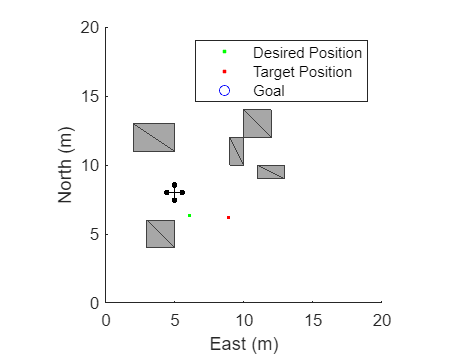



% Simulate 
for idx = 1:1
    [isupdated,lidarSampleTime,pt] = read(lidar);
    xLidar = reshape(pt.Location(:,:,1),[],1);
    yLidar = reshape(pt.Location(:,:,2),[],1);
    zLidar = reshape(pt.Location(:,:,3),[],1);

    sensorPoints = [xLidar yLidar zLidar];
  
    [targetPosition,~,desYaw] = wf(uavPose(1:4),lookaheadWF);
    uavPose(1:4)
    targetPosition
    [desiredDirection,desiredYaw,status] = vfh3D(uavPosition,uavOrientation, ...
                                                 sensorPoints,targetPosition)
    
    % Visualize the histogram.
    figure(2)
    show(vfh3D,PlotsToShow="2D Inflated Histogram");

    % Select desired position along the obtacle-free direction.
    desiredPosition = uavPosition + lookaheadOA*desiredDirection;
    desiredPosition    

    [t,y] = ode23(@(t,x)exampleHelperDerivative(t,x,model,desiredPosition,desiredYaw,kp,kd,ki,kyaw), ...
                  tStart:hStep:tStart + tStep,initialState);

    % Store data.
    tTotal((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1)) = t;
    states((idx-1)*(tStep/hStep+1) + 1:idx*(tStep/hStep+1),:) = y;

    % Update states.
    uavPosition = y(end,1:3)';
    uavOrientEul = y(end,7:9)';
    uavOrientation = eul2quat(uavOrientEul')';
    tStart = t(end);
    initialState = y(end,:);
  
    % Plot the path.
    desPosition = plot3(desiredPosition(2),desiredPosition(1),-desiredPosition(3),".g",Parent=ax);
    tgtPosition = plot3(targetPosition(2),targetPosition(1),-targetPosition(3),".r",Parent=ax);
    goalPosition = plot3(wf.Waypoints(end,2),wf.Waypoints(end,1),-wf.Waypoints(end,3),"ob",Parent=ax);
    legend(ax,[desPosition tgtPosition goalPosition],["Desired Position","Target Position","Goal"])
   
    if isupdated
        % Use fast update to move platform visualization frames.
        show3D(scene,Parent=ax,Time=lidarSampleTime,FastUpdate=true);
        % Move the platform.
        move(plat,[uavPosition' y(end,4:6) zeros(1,3) eul2quat(uavOrientEul') zeros(1,3)]);
        drawnow limitrate
    end

    % Advance scene simulation time.
    advance(scene);

    % Update all sensors in the scene.
    updateSensors(scene)

    uavPose = [uavPosition; quat2eul(uavOrientation',"ZYX")'];
end